PT4 Right

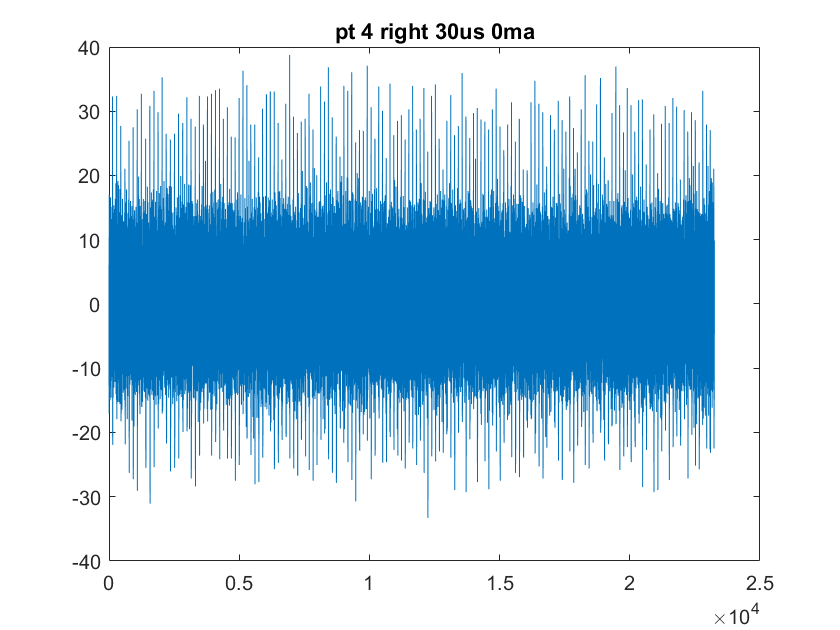

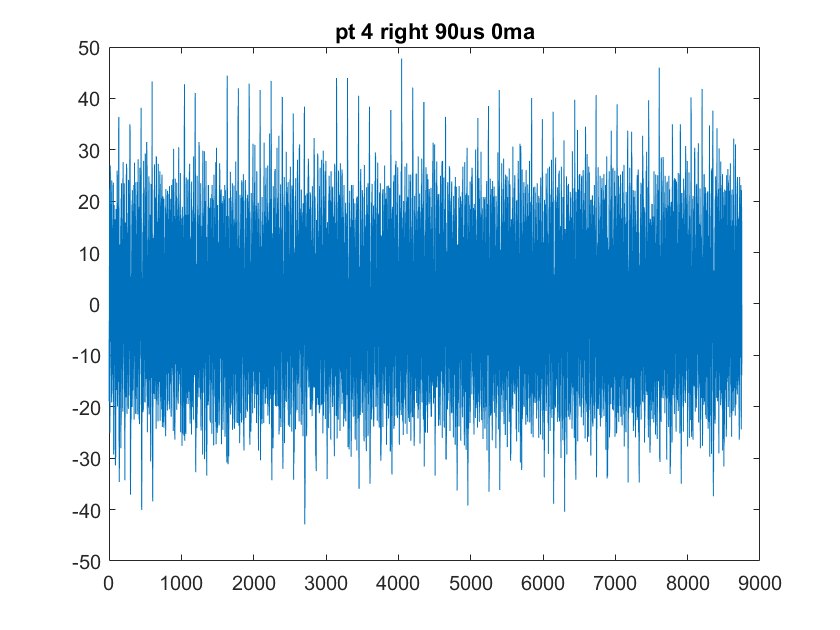

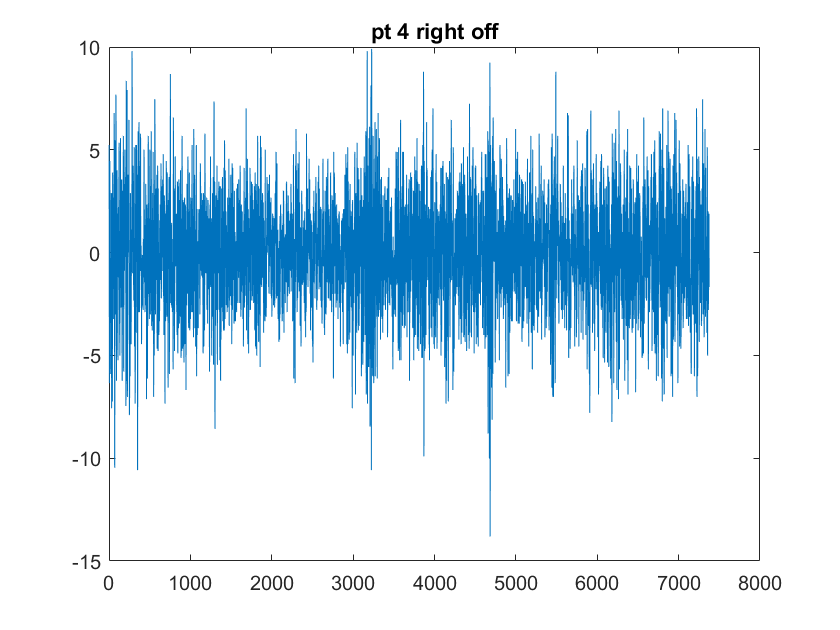

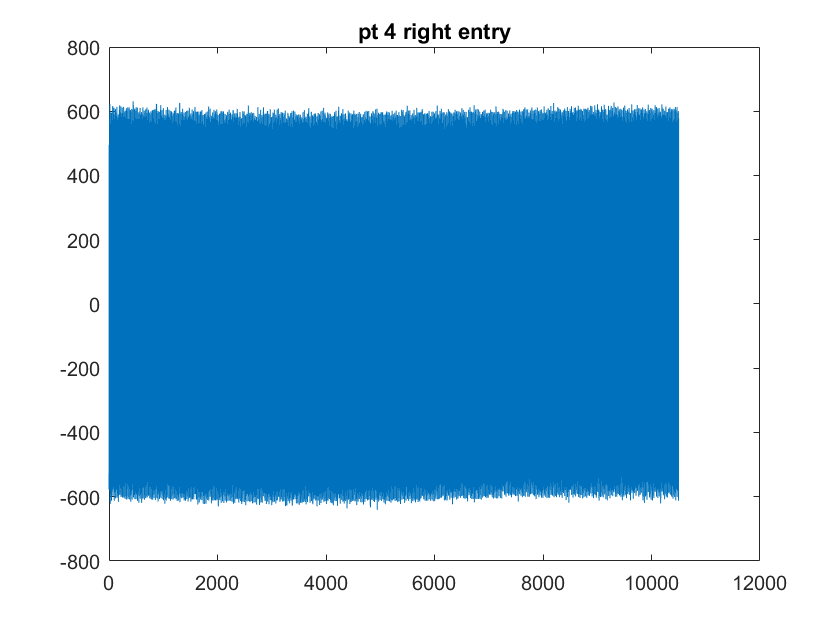

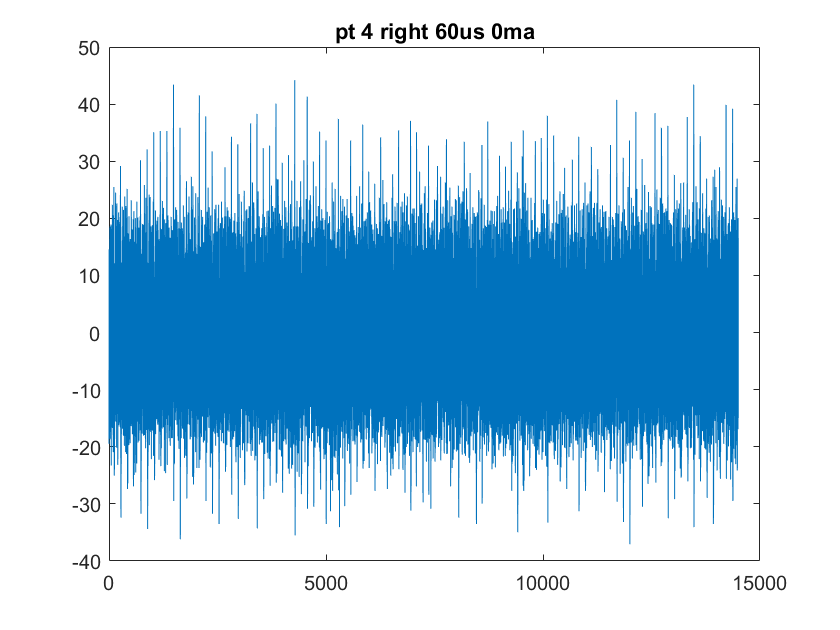

%can try filtering similar to function previously 
clear all;
figure;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_20210819T151123.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    pt = "pt 4 right "; 
    legendVal{i} = ((append(pt, pw, "us ", ma, "ma")));
end 
legendVal{3} = append(pt, "off");
legendVal{4} = append(pt, "entry"); 

%create plot of index vs voltage LFP data 
for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
    figname = append(legendVal{i}, ".fig"); 
    savefig(figname)
end 

### Code to Create Plot of all Data 

Run the section of interest above using "run section" to generate relevant data 

Run this section to plot all of the raw LFP data on the same plot 

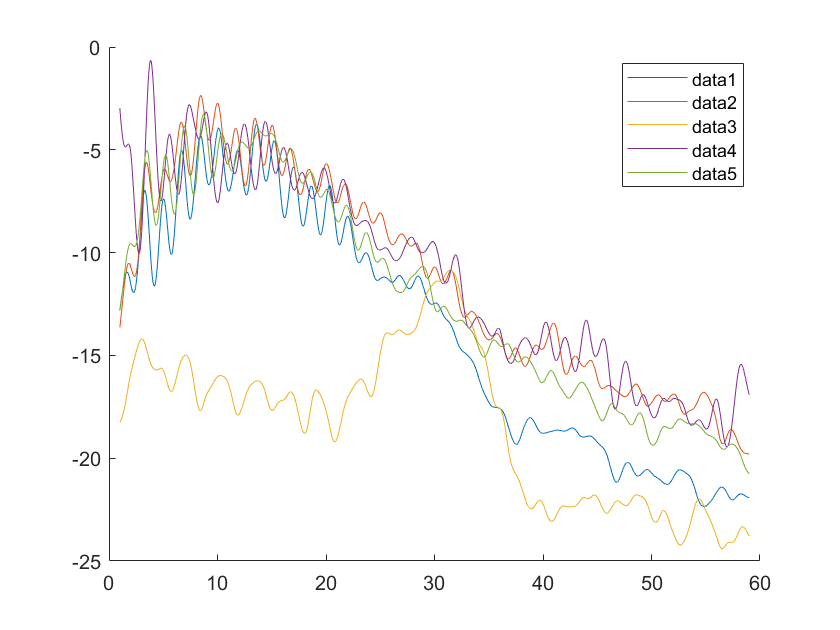

figure
for i = 1:leng
    field = append("treatment", num2str(i));
    [outDAT] = proc1(data.(field).timeDomain); 
    %collect time domain data from given field in Data strcut I made 

    hold on
    plot(outDAT.freq,outDAT.pwr)
end
legend()

function [outDAT] = proc1(dataIN)
%purpose of this fucntion is really to proces the data in a
%general and nonspecific way 

hp = highpass(dataIN,0.8,250);
lp = lowpass(hp,59,250);
%dont recall how these numbers were created 
[x,y] = pspectrum(lp,250,'FrequencyLimits',[1 59]);

xl = 10*log10(x);
%plots bode-ish of power from pspectrum
x2 = smoothdata(xl,'gaussian',150);
%smooth the bode 

outDAT.freq = y;
outDAT.pwr = x2;

end